clear all
close all
clc

model_name = 'SW_CS_LTB';

eval(['dynare ', model_name, '.mod noclearall nostrict nolog']);

Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 46 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.



STEADY-STATE RESULTS:

labobs  		 0.5509
robs    		 2.73374
pinfobs 		 2
dy      		 0.4
dc      		 0.4
dinve   		 0.4
dw      		 0.4
ewma    		 0
epinfma 		 0
zcapf   		 4.55205e-19
rkf     		 5.47891e-19
kf      		 1.76913e-16
pkf     		 0
cf      		 -3.26717e-16
invef   		 1.76458e-16
yf      		 2.85073e-16
labf    		 1.77634e-16
wf      		 -1.73018e-19
rrf     		 -8.34296e-16
mc      		 -7.45272e-15
zcap    		 -3.26522e-15
rk      		 -3.93006e-15
k       		 -3.26522e-15
pk      		 0
c       		 1.24727e-15
inve    		 0
y       		 4.13546e-16
lab     		 1.36985e-15
pinf    		 2
w       		 -8.56514e-15
r       		 -2.22045e-15
a       		 0
b       		 -1.02282e-16
g       		 4.44089e-16
qs      		 0
ms      		 4.22083e-17
spinf   		 1.08377e-16
sw      		 9.53245e-17
kpf     		 1.76458e-16
kp      		 0
rr      		 -0.733743
v       		 -1.22675e-15
s       		 1.92556e-19
vstar   		 1.164e-16
rn      		 2.73374
q       		 1.40423e-14

EIGENVALUES:
         Modulus             Real        Im

MODEL SUMMARY

  Number of variables:         46
  Number of stochastic shocks: 8
  Number of state variables:   23
  Number of jumpers:           14
  Number of static variables:  15


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables          ea        eb        eg       eqs        em     epinf        ew     eps_s
ea           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eb           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eg           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eqs          0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
em           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
epinf        0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
ew           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eps_s        0.000000  0.000000  0.00

THEORETICAL MOMENTS
VARIABLE         MEAN  STD. DEV.   VARIANCE
labobs         0.5509     0.0000     0.0000
robs           2.7337     0.0000     0.0000
pinfobs        2.0000     0.0000     0.0000
dy             0.4000     0.0000     0.0000
dc             0.4000     0.0000     0.0000
dinve          0.4000     0.0000     0.0000
dw             0.4000     0.0000     0.0000
ewma           0.0000     0.0000     0.0000
epinfma        0.0000     0.0000     0.0000
zcapf          0.0000     0.0000     0.0000
rkf            0.0000     0.0000     0.0000
kf             0.0000     0.0000     0.0000
pkf            0.0000     0.0000     0.0000
cf            -0.0000     0.0000     0.0000
invef          0.0000     0.0000     0.0000
yf             0.0000     0.0000     0.0000
labf           0.0000     0.0000     0.0000
wf            -0.0000     0.0000     0.0000
rrf           -0.0000     0.0000     0.0000
mc            -0.0000     0.0000     0.0000
zcap          -0.0000     0.0000     0.0000
rk          


folder_path = fullfile(pwd, model_name); % 'pwd' ensures an absolute path from the current working directory
if ~exist(folder_path, 'dir')
   mkdir(folder_path);
end

% Load the estimated posterior paramters from Dynare
addpath("SW_LTB_RR\metropolis");
load("SW_LTB_RR_mh1_blck1.mat");

## Setting the Parameters

inflation_target = 1.005;
Tstar = 6; %default Ta = 4

### Fiscal-led regime

CRPI_fis = 0.5;
R_fis = 0;
% CRPI_fis = 0.5;
% R_fis = 0;

### Monetary-led regime

CRPI_mon = 2.0443;
R_mon = 0.35;

## Loop to Plot IRFs

### Fiscal Regime

Calculating & Plotting Sacrifice ratio for cold turkey fiscal-led disinflation


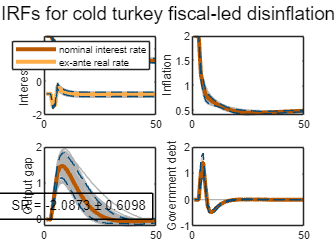

Calculating & Plotting Sacrifice ratio for fiscal-led disinflation with announcement 1 period ahead


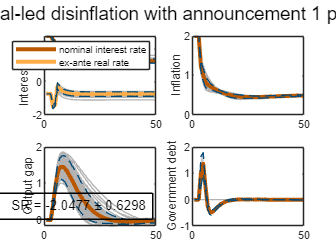

Calculating & Plotting Sacrifice ratio for fiscal-led disinflation with announcement 2 period ahead


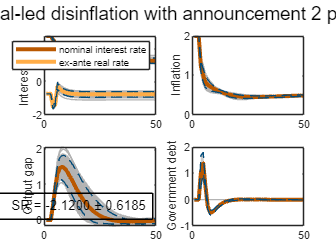

for T = 4:6
    if T - 4 > 0
        message = sprintf('Calculating & Plotting Sacrifice ratio for fiscal-led disinflation with announcement %d period ahead', T-4);
        disp(message)
    else
        disp("Calculating & Plotting Sacrifice ratio for cold turkey fiscal-led disinflation")
    end
    [fig_fis{T-3}, SR_fis{T-3}] = autoplot(x2, estim_params_, options_,M_,oo_, inflation_target, CRPI_fis, R_fis, 4, Tstar);
    set(gcf, 'Position', [100, 100, 1000, 600]);
    
    if T - 4 > 0
        graphTitle = sprintf('IRFs for fiscal-led disinflation with announcement %d period ahead', T-4);
    else
        graphTitle = 'IRFs for cold turkey fiscal-led disinflation';
    end
    suptitle(graphTitle);

    filename = fullfile(folder_path, sprintf('An%d_Fis.png', T-4));
    saveas(gcf, filename);
end

### Monetary Regime

for T = 4:6
    if T - 4 > 0
        message = sprintf('Calculating & Plotting Sacrifice ratio for monetary-led disinflation with announcement %d period ahead', T-4);
        disp(message)
    else
        disp("Calculating & Plotting Sacrifice ratio for cold turkey monetary-led disinflation")
    end
    [fig_mon{T-3}, SR_mon{T-3}] = autoplot(x2, estim_params_, options_,M_,oo_, inflation_target, CRPI_mon, R_mon, 4, Tstar);
    set(gcf, 'Position', [100, 100, 1000, 600]);

    if T - 4 > 0
        graphTitle = sprintf('IRFs for monetary-led disinflation with announcement %d period ahead', T-4);
    else
        graphTitle = 'IRFs for cold turkey monetary-led disinflation';
    end
    suptitle(graphTitle);

   % Generate a customized filename and save the figure
    filename = fullfile(folder_path, sprintf('An%d_Mon.png', T-4));
    saveas(gcf, filename);
end

Calculating & Plotting Sacrifice ratio for cold turkey monetary-led disinflation


Dot indexing is not supported for variables of this type.

Error in autoplot (line 11)
SET.param_crosswalk = estim_params_.param_vals(:,1);

## Generate Table for Sacrifice Ratio

SR_fis_table = table([SR_fis{:}]', 'VariableNames', {'SR_fis'});
SR_mon_table = table([SR_mon{:}]', 'VariableNames', {'SR_mon'});

% Create the status variable
status = {'Cold-turkey'; 'Announced 1'; 'Announced 2'};

% Create a table from the status variable
status_table = table(status, 'VariableNames', {'Status'});

% Concatenate the tables horizontally
combined_table = [status_table, SR_fis_table, SR_mon_table];